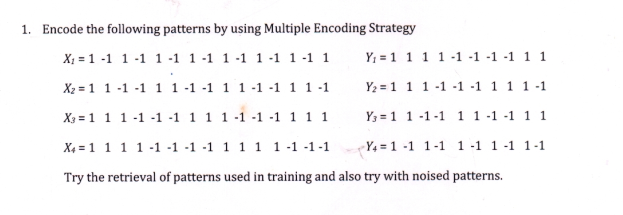

X1 = [1	-1	1	-1	1	-1	1	-1	1	-1	1	-1	1	-1	1] ;
X2 = [1	1	-1	-1	1	1	-1	-1	1	1	-1	-1	1	1	-1] ;
X3 = [1	1	1	-1	-1	-1	1	1	1	-1	-1	-1	1	1	1 ] ;
X4 = [1	1	1	1	-1	-1	-1	-1	1	1	1	1	-1	-1	-1] ;

Y1 = [1	1	1	1	-1	-1	-1	-1	1	1] ;
Y2 = [1	1	1	-1	-1	-1	1	1	1	-1] ;
Y3 = [1	1	-1	-1	1	1	-1	-1	1	1] ;
Y4 = [1	-1	1	-1	1	-1	1	-1	1	-1] ;

X = containers.Map({1,2,3,4},{X1,X2,X3,X4});
Y = containers.Map({1,2,3,4},{Y1,Y2,Y3,Y4});

% Training
w = zeros(15,10);
for i = 1:4
    x = reshape(X(i),[],1);
    y = reshape(Y(i),[],1);
    w = w + x*y' ;
end
w

w =      4     2     2    -2     0    -2     0    -2     4     0
     2     0     0    -4     2     0     2     0     2    -2
     2     0     0     0     2     0    -2    -4     2     2
    -2    -4     0     0     2     0     2     0    -2    -2
     0     2     2     2    -4    -2     0     2     0     0
    -2     0     0     0    -2     0     2     4    -2    -2
     0     2    -2     2     0     2    -4    -2     0     4
    -2     0    -4     0     2     4    -2     0    -2     2
     4     2     2    -2     0    -2     0    -2     4     0
     0    -2     2    -2     0    -2     4     2     0    -4


max_iter = 10 ;
for i = 1:4
    x = X(i);
    for z = 1:max_iter
        out = x*w ;
        out = hardlims(out);
        if out == Y(i)
            fprintf("%d point is retrieved correctly",i)
            X(i)
            out
            Y(i)
            break
        else
            x = hardlims(out*w');
        end
    end
end

1 is recognised

ans =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1


out =      1     1     1     1    -1    -1    -1    -1     1     1


ans =      1     1     1     1    -1    -1    -1    -1     1     1


2 is recognised

ans =      1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1


out =      1     1     1    -1    -1    -1     1     1     1    -1


ans =      1     1     1    -1    -1    -1     1     1     1    -1


3 is recognised

ans =      1     1     1    -1    -1    -1     1     1     1    -1    -1    -1     1     1     1


out =      1     1    -1    -1     1     1    -1    -1     1     1


ans =      1     1    -1    -1     1     1    -1    -1     1     1


4 is recognised

ans =      1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1


out =      1    -1     1    -1     1    -1     1    -1     1    -1


ans =      1    -1     1    -1     1    -1     1    -1     1    -1


% Noised Data
Noise_Input = containers.Map({1,2,3,4},{noise(X1,10),noise(X2,10),noise(X2,10),noise(X2,10)});
fprintf("Noised Patterns are\n")

Noised Patterns are


for k =1:4
    disp(Noise_Input(k))
end

     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1    -1

     1     1     1    -1     1     1    -1    -1    -1     1    -1    -1     1     1    -1

     1     1     1     1     1     1    -1    -1     1     1    -1    -1     1     1    -1

     1     1    -1     1     1     1    -1    -1     1     1    -1    -1    -1     1    -1



max_iter = 10 ;
for i = 1:4
    x = Noise_Input(i);
    flag = 0;
    for z = 1:max_iter
        out = x*w ;
        out = hardlims(out);
        for k = 1:4
            if out == Y(k)
                fprintf("noise pattern %d retrieved output pattern %d\n",i,k);
                flag = 1;
                break
            end
        end
        if flag == 1
            break
        end
        x = hardlims(out*w');
    end
end

noise pattern 1 retrieved output pattern 1
noise pattern 2 retrieved output pattern 2
noise pattern 3 retrieved output pattern 2
noise pattern 4 retrieved output pattern 2


function A = noise(X,per)
    k = numel(X);
    n = ceil((k*per)/100) ;
    index = randi(k,n,1);
    for i = index
        X(i) = X(i)*-1 ;
    end
    A=X;
end